# Optimization - with space stops

clc;
clear;
close all;

[param, weather, route, driver] = loadData();

effLoss = load("inefficiency.mat").effLoss;
tempCF = load("temperatureCF.mat").tempCF;
velSafe = load("optimalMeanVelocity.mat").velMeanOpt_unitedStops;

cd("C:\Users\giaco\Git_Repositories\Bachelor_Arbeit\Codes\Optimization");

interestDay = datetime(2020,10,20);
enhanceFactor = 1.8;
raceDays = 5;
plotIsRequested = false;
weatherSim = weatherSimFullRace(interestDay, enhanceFactor, raceDays, plotIsRequested);

### Constant values

Colours for plots

colour = struct();
colour.loss = 'r';
colour.solar = 'g';
colour.battery = 'magenta';

Initial and safe to spend battery energy

SoCmin = 0.1;
Ebatmax = param.battery.Emax; %J
EbatSafe = Ebatmax * (1 - SoCmin); %J

Cumulative solar energy

EcumSolar = cumtrapz(weatherSim.irradiance.GtotalSec) * param.pv.area * param.pv.eff * tempCF * param.pv.loss.total; %J
%%%%%%%%%%%%%%%%%%%%%%% CORRECTION FOR PLOTS
EcumSolar = EcumSolar * 1.1;

Roll force

Froll = param.constants.roll; %N

# Time

### Nights cut

horizon_8_17 = logical(weatherSim.irradiance.driving_8_17_Sec); %conversion to logical
Gtotal_8_17 = weatherSim.irradiance.GtotalSec(horizon_8_17);
dayNum_8_17 = weatherSim.irradiance.dayNumSec(horizon_8_17);
EcumSolar_8_17 = EcumSolar(horizon_8_17);

time_8_17 = weatherSim.irradiance.timeSec(horizon_8_17); %CHECK SHIFT BY ONE OF NIGHTS STOP FROM THE SECOND ONE
timeLen_8_17 = length(time_8_17);
timeSec_8_17 = linspace(1, timeLen_8_17, timeLen_8_17)';

[timeSec_driving, controlStopBeginSec, finishSec, horizon_driving] = timeVecCreatorForPlots(velSafe, timeSec_8_17);

Space2time: correction of night stops to plot

% CHECK SHIFT BY ONE BETWEEN SEC AND HOUR, MAYBE IS THE FUNCTION TIMEVEC
nightStopHour_17 = (7 : 9 : 9*(raceDays))'; %h
nightStopSec_17 = seconds(hours(nightStopHour_17)); %s

timeBeginIncNextStop = controlStopBeginSec + seconds(minutes(30)) * (0 : length(controlStopBeginSec)-1)';
timeBeginIncNextStopHour = timeBeginIncNextStop / 3600;
timeEndIncNextStopHour = timeBeginIncNextStopHour + hours(minutes(30));
timeBeginStopHour = controlStopBeginSec / 3600;

nightStopHour_17_cut = nightStopHour_17;
idx = 1;
for j = 1:length(timeBeginStopHour)
    if nightStopHour_17_cut(idx) > timeBeginStopHour(j)
        nightStopHour_17_cut(idx) = nightStopHour_17_cut(idx) - hours(minutes(30));
    else
        idx = idx + 1;
        nightStopHour_17_cut(idx) = nightStopHour_17_cut(idx) - j * hours(minutes(30));
    end % if
end % for

nightStopSec_17_cut = seconds(hours(nightStopHour_17_cut));

%overlap night/spaceStop correction
overlapNights = false(size(nightStopHour_17));
overlapSpaceStops = false(driver.numSpaceStops, 1);
for i = 1:length(nightStopHour_17)
    overlapIsDetected = timeBeginIncNextStopHour < nightStopHour_17(i) & nightStopHour_17(i) < timeEndIncNextStopHour; %DANGER WHEN EQUAL? ONE SHOULD BE =

    overlapSpaceStops = overlapSpaceStops | overlapIsDetected;
    overlapNights(i) = overlapNights(i) | boolean(sum(overlapIsDetected));
end % for
nightStopSec_17_cut(overlapNights == 1) = controlStopBeginSec(overlapSpaceStops == 1);

Gtotal_driving = Gtotal_8_17(horizon_driving);
dayNum_driving = dayNum_8_17(horizon_driving);
EcumSolar_driving = EcumSolar_8_17(horizon_driving);
EbudgetTot_driving = EcumSolar_driving + EbatSafe;
Faero_driving = param.constants.aero * (driver.finishLocDist ./ timeSec_driving).^2; %N
Eloss_driving = driver.finishLocDist / effLoss * (Froll + Faero_driving);

#### Find optimal point

[timeOpt_driving, velMeanOpt_driving] = optimalTimeVelocityEstimator(Eloss_driving, EbudgetTot_driving);

Optimal driving time: 28.55 h 
Optimal velocity: 106.01 km/h

#### Energy, irradiance vs driving time

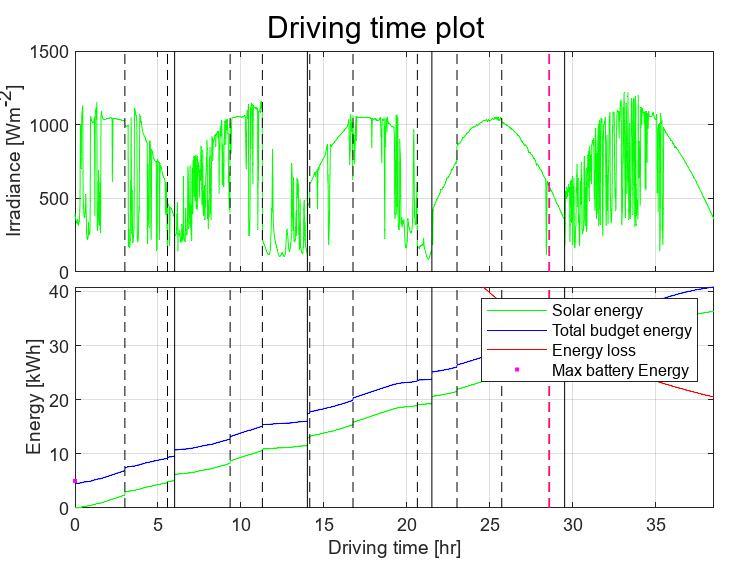

title = 'Driving time plot';
synchronizeXAxes = true;
xaxisTime = timeSec_driving / 3600;
xlimVecTime = [0, xaxisTime(end)];
ylimVecTime = [0, J2kWh(EcumSolar_driving(end)+EbatSafe)];
builder = VerticalPlotBuilder(synchronizeXAxes, title);

builder.addPlot(xaxisTime, Gtotal_8_17(horizon_driving),'-','Color',colour.solar);
builder.addLines('vertical', nightStopSec_17_cut / 3600, 'k');
builder.addLines('vertical', timeOpt_driving / 3600, 'r--');
builder.addLines('vertical', controlStopBeginSec / 3600, 'k--');
builder.addLines('vertical', finishSec / 3600, 'magenta--');
builder.setYlabel("Irradiance [Wm^{-2}]");
builder.setXlim(xlimVecTime)

builder.startNewSubplot();
builder.addPlot(xaxisTime, J2kWh(EcumSolar_driving),'-','Color',colour.solar);
builder.addPlot(xaxisTime, J2kWh(EbudgetTot_driving),'-','Color','b');
builder.addPlot(xaxisTime, J2kWh(Eloss_driving),'-','Color',colour.loss);
builder.addPlot(0, J2kWh(Ebatmax),'.','Color',colour.battery);
builder.addPlot(timeOpt_driving / 3600, J2kWh(Eloss_driving(timeOpt_driving)), 'r.', 'MarkerSize', 20)
builder.addLines('vertical', nightStopSec_17_cut / 3600, 'k');
builder.addLines('vertical', controlStopBeginSec / 3600, 'k--');
builder.addLines('vertical', finishSec / 3600, 'magenta--');
builder.addLines('vertical', timeOpt_driving / 3600, 'r--');
builder.setYlabel("Energy [kWh]")
builder.setLegend("Solar energy","Total budget energy","Energy loss","Max battery Energy")
builder.setXlim(xlimVecTime)
builder.setYlim(ylimVecTime)

builder.setXlabel("Driving time [hr]");
builder.drawNow()

## Distance Analysis

[timeDist_driving, ~, ~, ~] = timeVecCreatorForPlots(velMeanOpt_driving, timeSec_8_17);
% distVec = timeDist_driving * velMeanOpt_driving;
distVec = timeDist_driving * velSafe;

altiInterp = interp1(route.dist, route.alti, distVec);
EpotDist = param.constants.gravity * altiInterp; %J

FaeroDist = param.constants.aero * velMeanOpt_driving.^2; %N
ElossDist = distVec / effLoss * (Froll + FaeroDist); %J

EBatDist = Ebatmax + EcumSolar_driving - ElossDist; % - EpotDist
SoCdist = EBatDist / Ebatmax; %valid also for time domain

Time2space: correction of night stops

timeStopDist = nightStopSec_17_cut * velSafe;

### Plot

#### Energy vs distance

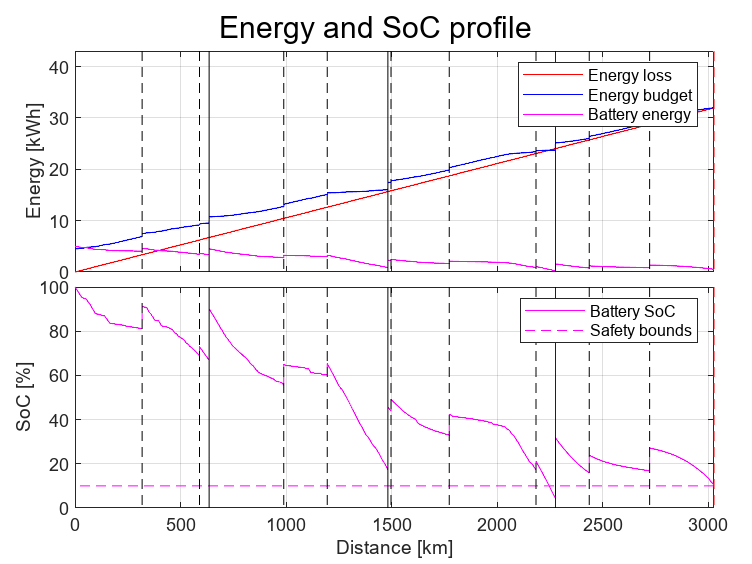

title = 'Energy and SoC profile';
synchronizeXAxes = true;
xaxisDist = distVec / 1000;
xlimVecDist = [0, driver.finishLocDist / 1000];
ylimVecDist = [0, max(J2kWh(ElossDist))];
builder = VerticalPlotBuilder(synchronizeXAxes, title);

builder.addPlot(xaxisDist, J2kWh(ElossDist),'-','Color',colour.loss);
builder.addPlot(xaxisDist, J2kWh(EbudgetTot_driving),'-','Color','b');
builder.addPlot(xaxisDist, J2kWh(EBatDist),'-','Color',colour.battery);
% builder.addPlot(0, J2kWh(Ebatmax),'.','Color',colour.battery);
builder.addLines('vertical', timeStopDist / 1000, 'k');
builder.addLines('vertical', driver.stopLocDist(2:end-1) / 1000, 'k--');
builder.addLines('vertical', driver.finishLocDist / 1000, 'r--');
builder.setYlabel("Energy [kWh]")
builder.setLegend("Energy loss","Energy budget","Battery energy")
builder.setXlim(xlimVecDist)
builder.setYlim(ylimVecDist)

builder.startNewSubplot();
builder.addPlot(xaxisDist, SoCdist * 100,'-','Color',colour.battery);
builder.addLines('horizontal', (1 - EbatSafe / Ebatmax) * 100,'--','Color',colour.battery);
builder.addLines('vertical', timeStopDist / 1000, 'k');
builder.addLines('vertical', driver.stopLocDist(2:end-1) / 1000, 'k--');
builder.addLines('vertical', driver.finishLocDist / 1000, 'r--');
builder.setYlabel("SoC [%]")
builder.setLegend("Battery SoC","Safety bounds")
builder.setXlim(xlimVecDist)
builder.setYlim([0, 100])

builder.setXlabel("Distance [km]");
builder.drawNow()

## Detection

Preparation for detection

finishSecIndex = find(finishSec >= timeSec_driving, 1, 'last');
% finishSecIndex = find(timeSec_driving <= finishSec, 1, 'last')
% finishSecIndex = find(finishSec <= timeSec_driving, 1, 'first')
% finishSecIndex = find(timeSec_driving >= finishSec, 1, 'first')

%search until detection
SoCdetectionHorizon = SoCdist(1:finishSecIndex);

lowSoCisDetected = min(SoCdetectionHorizon) < SoCmin;
% [lowestSoc, lowestSocIdx] = min(SoCdetectionHorizon)
if lowSoCisDetected
    indexDetection = find(SoCdist == min(SoCdetectionHorizon)); %also time
    numDayDetection = dayNum_driving(indexDetection);
end % if

numDayDetection = 3; %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% CHECK AGAIN

%check where was detected
detectionFoundDuringControlStop = controlStopBeginSec == indexDetection;
detectionFoundDuringNightStop = nightStopSec_17_cut == indexDetection;

detectionNightIndex_driving = max(find(diff(dayNum_driving) == 1, numDayDetection, 'first'));
EsolarUntilDetection = EcumSolar_driving(detectionNightIndex_driving);
timeUntilDetectionSec_driving = detectionNightIndex_driving;

#### Safe velocity estimation

p = param.constants.roll / param.constants.aero;
q = -effLoss * (EbatSafe + EsolarUntilDetection) / (timeUntilDetectionSec_driving * param.constants.aero);
velSafe = cardanoDepressed3rd(p, q);

fprintf('Safe velocity: %3.2f km/h', velSafe * 3.6)

Safe velocity: 105.47 km/h

timeSafe = driver.finishLocDist / velSafe;
fprintf('Optimal driving time: %3.2f h', timeSafe / 3600)

Optimal driving time: 28.70 h


distVecSafe = timeSec_driving * velSafe;

altiInterpSafe = interp1(route.dist, route.alti, distVecSafe);
EpotDistSafe = param.constants.gravity * altiInterpSafe; %J

FaeroDistSafe = param.constants.aero * velSafe^2; %N
ElossDistSafe = distVecSafe / effLoss * (Froll + FaeroDistSafe); %J

EBatDistSafe = Ebatmax + EcumSolar_driving - ElossDistSafe; % - EpotDistSafe
SoCdistSafe = EBatDistSafe / Ebatmax;

### Plot

#### Energy, irradiance vs driving time

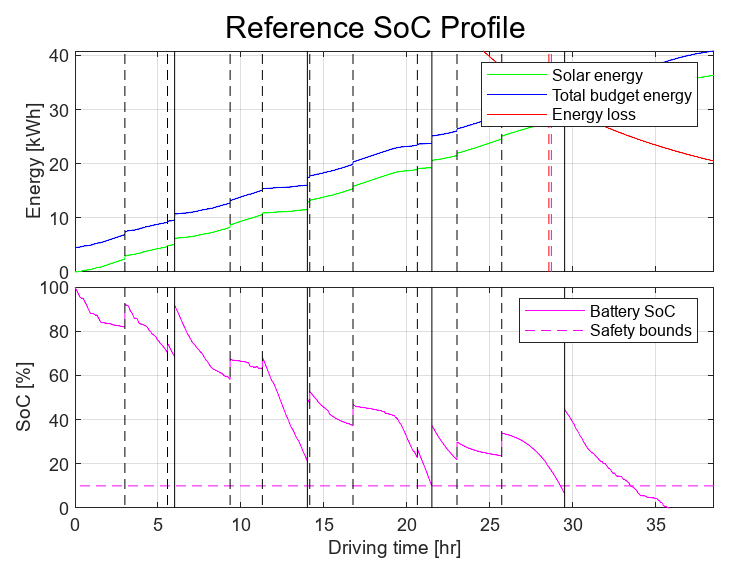

title = 'Reference SoC Profile';
synchronizeXAxes = true;
xaxisTime = timeSec_driving / 3600;
xlimVecTime = [0, xaxisTime(end)];
ylimVecTime = [0, J2kWh(EcumSolar_driving(end)+EbatSafe)];
builder = VerticalPlotBuilder(synchronizeXAxes, title);

builder.addPlot(xaxisTime, J2kWh(EcumSolar_driving),'-','Color',colour.solar);
builder.addPlot(xaxisTime, J2kWh(EbudgetTot_driving),'-','Color','b');
builder.addPlot(xaxisTime, J2kWh(Eloss_driving),'-','Color',colour.loss);
% builder.addPlot(0, J2kWh(Ebatmax),'.','Color',colour.battery);
builder.addPlot(timeOpt_driving / 3600, J2kWh(Eloss_driving(timeOpt_driving)), 'r.', 'MarkerSize', 20)
builder.addLines('vertical', nightStopSec_17_cut / 3600, 'k');
builder.addLines('vertical', controlStopBeginSec / 3600, 'k--');
% builder.addLines('vertical', finishSec / 3600, 'magenta--');
builder.addLines('vertical', timeOpt_driving / 3600, 'r--');
builder.addLines('vertical', timeSafe / 3600, 'magenta--');
builder.setYlabel("Energy [kWh]")
builder.setLegend("Solar energy","Total budget energy","Energy loss")
builder.setXlim(xlimVecTime)
builder.setYlim(ylimVecTime)

builder.startNewSubplot();
builder.addPlot(xaxisTime, SoCdistSafe * 100,'-','Color',colour.battery);
builder.addLines('horizontal', (1 - EbatSafe / Ebatmax) * 100,'--','Color',colour.battery);
builder.addLines('vertical', nightStopSec_17_cut / 3600, 'k');
builder.addLines('vertical', controlStopBeginSec / 3600, 'k--');
builder.setYlabel("SoC [%]")
builder.setLegend("Battery SoC","Safety bounds")
builder.setXlim(xlimVecTime)
builder.setYlim([0, 100])

builder.setXlabel("Driving time [hr]");
builder.drawNow()

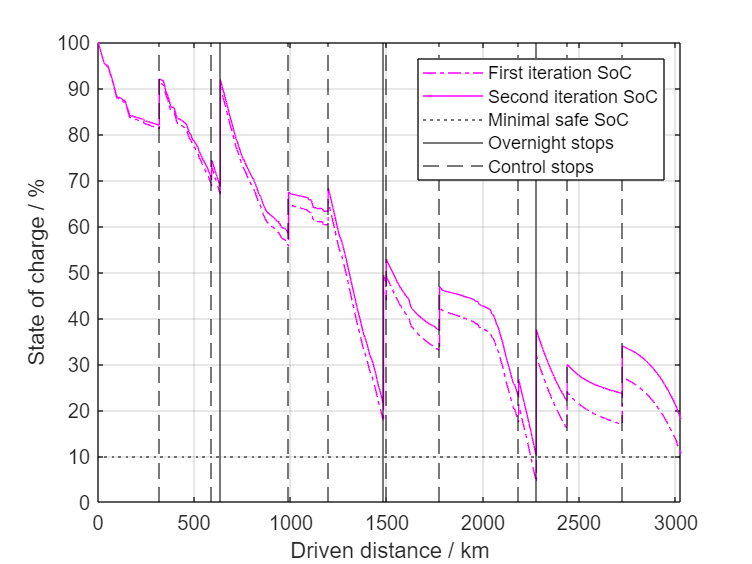

savePlots = false;

figure
hold on
plot(xaxisDist, SoCdist * 100,'-.','Color',colour.battery,'DisplayName','First iteration SoC');
plot(xaxisDist, SoCdistSafe * 100,'-','Color',colour.battery,'DisplayName','Second iteration SoC');
yline((1 - EbatSafe / Ebatmax) * 100,':','Color','k','DisplayName','Minimal safe SoC');
xline(timeStopDist / 1000, 'k','HandleVisibility','off');
yline(4000,'k','DisplayName','Overnight stops');
xline(driver.stopLocDist(2:end-1) / 1000, 'k--','HandleVisibility','off');
yline(4000,'k--','DisplayName','Control stops');
xlim(xlimVecDist)
ylim([0, 100])
xlabel('Driven distance / km')
ylabel('State of charge / %')
legend()
box on
grid on


folder_save_plots = 'C:\Users\giaco\Git_Repositories\Bachelor_Arbeit\Presentation\Final\Matlab Plots';
addpath(folder_save_plots);

if savePlots
    filename_save = 'SoCsafe_dist_results';
    export_fig(gcf,[char(filename_save),'.png'],'-opengl','-transparent','-r600') %for PP
    movefile([char(filename_save),'.png'], folder_save_plots)
end

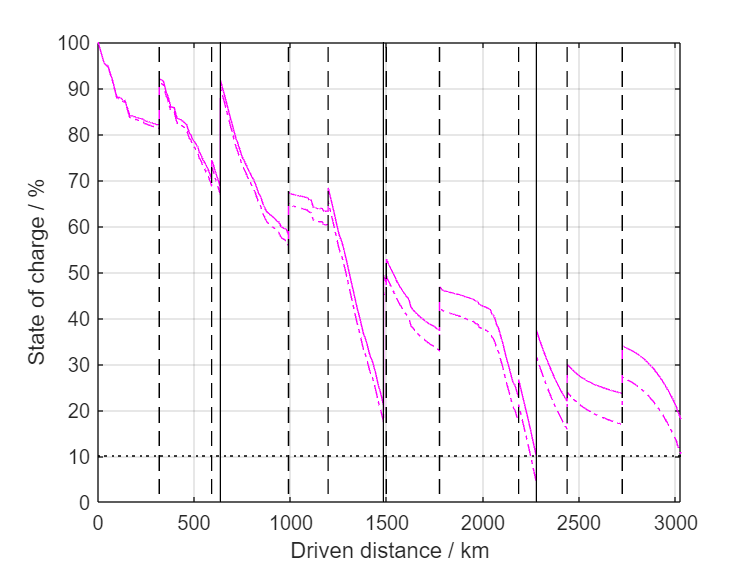

savePlots = false;
step = 8;
xaxisDistPlot = xaxisDist(1:step:end);

figure
hold on
plot(xaxisDistPlot, SoCdist(1:step:end) * 100,'-.','Color',colour.battery)
plot(xaxisDistPlot, SoCdistSafe(1:step:end) * 100,'-','Color',colour.battery)
plotLines(gca, 'horizontal', (1 - EbatSafe / Ebatmax) * 100, 'k:')
plotLines(gca, 'vertical', timeStopDist / 1000, 'k')
plotLines(gca, 'vertical', driver.stopLocDist(2:end-1) / 1000, 'k--')
xlim(xlimVecDist)
ylim([0, 100])
xlabel('Driven distance / km')
ylabel('State of charge / %')
box on
grid on


if savePlots
    figureName = 'resultsSoCsafe';
    latexMatlabPlotSaver(figureName, 'cleanFigure', true)
end % if

## Function

function [timeSec_driving, controlStopBeginSec, finishSec, horizon_driving] = timeVecCreatorForPlots(velocity, timeSec_8_17)
%with a given velocity we can cut the time plot corresponding to that specific stop location
    
persistent driver;
if isempty(driver)
    [~, ~, ~, driver] = loadData();
end % if

controlStopBeginSec = driver.stopLocDist(2:end-1) / velocity; %s ready to be plotted
finishSec = driver.stopLocDist(end) / velocity; %s
controlStopEndStops = controlStopBeginSec + seconds(minutes(30)); %s

horizon_spaceStop = false(size(timeSec_8_17));
for i = 1:driver.numSpaceStops
    %accounting for previous stops. Save only if between begin and end of
    %space stops
    tmp = (controlStopBeginSec(i) + (i-1)*seconds(minutes(30))) < timeSec_8_17 & timeSec_8_17 <= (controlStopEndStops(i) + (i-1)*seconds(minutes(30))); %DANGER WHEN EQUAL? ONE SHOULD BE =
    horizon_spaceStop = horizon_spaceStop | tmp; %update boolean vector
end % for

horizon_driving = ~horizon_spaceStop; %opposite, since nights stops already cut off
time_driving = timeSec_8_17(horizon_driving);

timeLen_driving = length(time_driving);
timeSec_driving = linspace(1, timeLen_driving, timeLen_driving)';
end % fct